# TP4 : 

- VIN Charles

- RECHAK LAMBERT Dorian

## Exercice 1 :

Instanciation des constantes :

w_p = 0.2*pi;
w_s = 0.3*pi;
R_p = 7; % db
A_s = 16;

### Question 1 :

Calcul de N

N = floor(log10( ...
        ((10^(R_p/10) - 1 )*(10^(A_s/10) - 1))...
        / ...
        (2*log10(w_p/w_s)) ...
       )) + 1;
N = real(N);
N

N = 3

Calcul de $w_c$

w_cp = w_p / (10^(R_p/10) - 1)^(1/(2*N));
w_cs = w_s / (10^(A_s/10) - 1)^(1/(2*N));
w_c = (w_cp + w_cs)/2;
w_c

w_c = 0.5053

### Question 2 :

On a donc $N=3$, donc 3*2=6 pôles. Dont 3 instables. Les pôles stables ont pour argument : 2pi/3, pi, 4pi/3

%Calcul des pôles
p_1 = w_c * exp(1i*2*pi/3);
p_2 = w_c * exp(1i*pi);
p_3 = w_c * exp(1i*4*pi/3);
p_1, p_2, p_3

p_1 = -0.2527 + 0.4376i

p_2 = -0.5053 + 0.0000i

p_3 = -0.2527 - 0.4376i

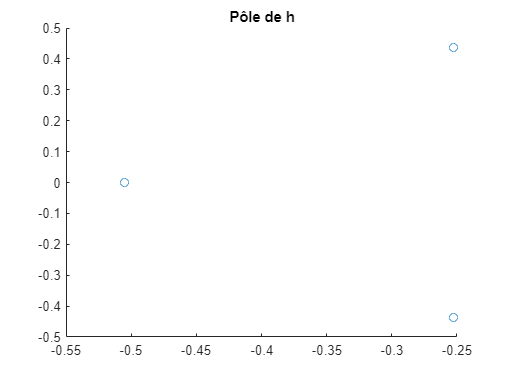

% Plot des pôles
x = real([p_1 p_2 p_3]);
y = imag([p_1 p_2 p_3]);
scatter(x,y);
title('Pôle de h');

### Question 3, 4:

f = 0 : 0.01 : 3;
w = 2*pi*f;
S = 1i*w;
H = w_c.^N ./ ((S - p_1).*(S - p_2).*(S - p_3));

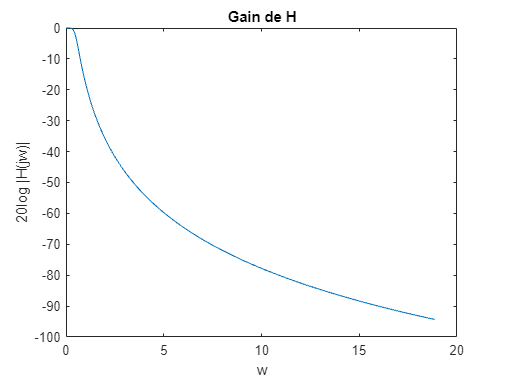

%Plot 
module = 20*log10(abs(H));
phase = unwrap(angle(H));
% IL FAUT VERIFIER ENTER 0.2pi et 0.3pi si on descend bien de r_p a_s
figure('name', 'Gain de H');
plot(w, module);
title('Gain de H');
xlabel('w');
ylabel('20log |H(jw)|');

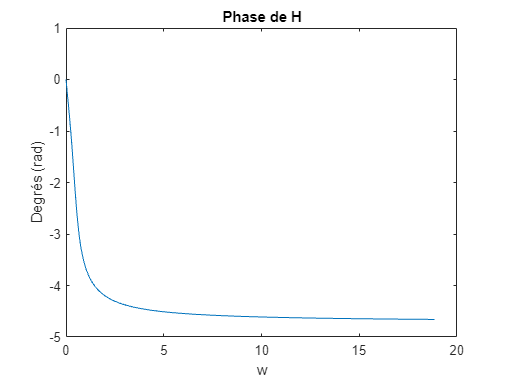


figure('name', 'Phase de H');
plot(w, phase);
title('Phase de H');
xlabel('w');
ylabel('Degrés (rad)');

#### Vérifions les caractéristiques du filtre : 

Pour cela je vais regarder le du module à $0\ldotp 2\pi$ et $0\ldotp 3\pi$. Il doit valoir respectivement $R_p =7\mathrm{db}$ et $A_s =16\mathrm{db}$ 

disp("=======0.2pi======")

=======0.2pi======


w(11)

ans = 0.6283

disp("L'indice 11 de w represente 0.2pi = 0.6283185307")

L'indice 11 de w represente 0.2pi = 0.6283185307


module(11)

ans = -6.7165

disp("On a le module de 0.2pi qui vaut environ -6.7165")

On a le module de 0.2pi qui vaut -6.7165



disp("")
disp("=======0.3pi======")

=======0.3pi======


w(16)

ans = 0.9425

disp("L'indice 16 de w represente 0.3pi = 0.9424777961")

L'indice 16 de w represente 0.3pi = 0.9424777961


module(16)

ans = -16.3438

disp("On a le module de 0.3pi qui vaut environ -16.3438")

On a le module de 0.3pi qui vaut -16.3438


On peut voir que les caractéristiques du filtre sont respecté. On a une légère approximation du au coté discret de la génération graphique.

### Question 5 :

Soit 

 
$$H(S) = \frac{w_c^N}{(S-p_1)(S-p_2)(S-p_3)} \\
    = \frac{w_c^N}{-p_1 S^2 - p_2 S^2 - p_3 S^2 + p_1 p_2 S + p_1 p_3 S + p_2 p_3 S - p_1 p_2 p_3 + S^3} \\ 
    = \frac{w_c^N}{S^3 + S^2 (-p_1-p_2-p_3) + S(p_1 p_2 + p_1 p_3 + p_2 p_3) - p_1 p_2 p_3 } \\ 
    = \frac{(w_c^N}{S^3 + S^2 a_2 + S a_1  + a_0 } \\
    = \frac{w_c^N S^{-3}}{1 + a_2 S^{-1} + a_1 S^{-2} + a_0 S^{-3}} \\$$


On a donc $a_2 = -p_1-p_2-p_3 \\
a_1 = p_1 p_2 + p_1 p_3 + p_2 p_3 \\
a_0 = - p_1 p_2 p_3 $

Finalement le circuit vaut :

## Exercice 2 :

### Conversion des paramètres

T = 1

T = 1

W_p = 0.2 * pi;
W_s = 0.3 * pi;

w_p = (2/T) * tan(W_p/2); % Conversion des paramètres
w_s = (2/T) * tan(W_s/2); % Conversion des paramètres
R_p = 7;
A_s = 16;

### Question 1 : 

N = floor(log10( ...
        ((10^(R_p/10) - 1 )*(10^(A_s/10) - 1))...
        / ...
        (2*log10(w_p/w_s)) ...
       )) + 1;
N = real(N);
N

N = 3

On a également N=3, donc 3*2=6 pôles. Dont 3 instables. Les pôles stables ont encore une fois pour argument : 2pi/3, pi, 4pi/3

w_cp = w_p / (10^(R_p/10) - 1)^(1/(2*N));
w_cs = w_s / (10^(A_s/10) - 1)^(1/(2*N));
w_c = (w_cp + w_cs)/2;

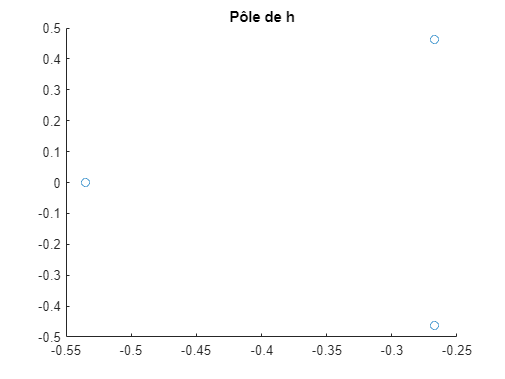

p_1 = w_c * exp(1i*2*pi/3);
p_2 = w_c * exp(1i*pi);
p_3 = w_c * exp(1i*4*pi/3);
x = real([p_1 p_2 p_3]);
y = imag([p_1 p_2 p_3]);
scatter(x,y);
title('Pôle de h');

p_1, p_2, p_3

p_1 = -0.2673 + 0.4630i

p_2 = -0.5347 + 0.0000i

p_3 = -0.2673 - 0.4630i

### Question 2 : 

#### Transformation bilinéaire

f = 0 : 0.01 : 3;
w = 2*pi*f;
Z = exp(1i*w);

S = (2/T) * (1-Z.^(-1))./(1 + Z.^(-1)); % Transformation bilinéaire
H = w_c.^N ./ ((S - p_1).*(S - p_2).*(S - p_3));

#### Plot du module et de la phase

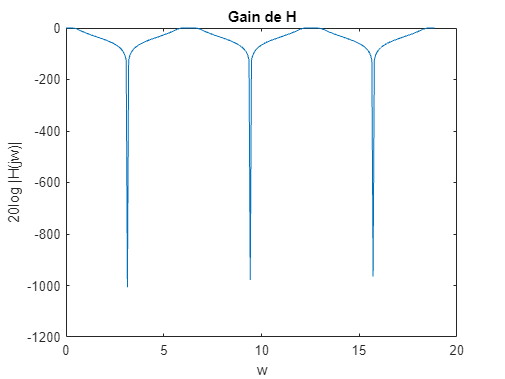

module = 20*log10(abs(H));
phase = unwrap(angle(H));

figure('name', 'Gain de H');
plot(w, module);
title('Gain de H');
xlabel('W');
ylabel('20log |H(jw)|');

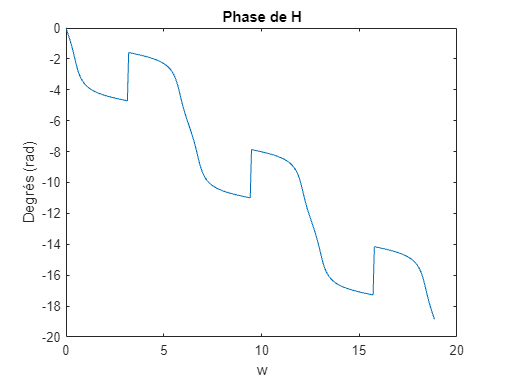


figure('name', 'Phase de H');
plot(w, phase);
title('Phase de H');
xlabel('W');
ylabel('Degrés (rad)');

#### Vérifions les caractéristiques du filtre : 

Pour cela je vais regarder le du module à $0\ldotp 2\pi$ et $0\ldotp 3\pi$. Il doit valoir respectivement $R_p =7\textrm{db}$ et $A_s =16\textrm{db}$ 

disp("=======0.2pi======")

=======0.2pi======


w(11)

ans = 0.6283

disp("L'indice 11 de W represente environ 0.2pi = 0.6283185307")

L'indice 11 de w represente 0.2pi = 0.6283185307


module(11)

ans = -6.2566

disp("On a le module de 0.2pi qui vaut environ -6.2566")

On a le module de 0.2pi qui vaut environ -6.7165



disp("")
disp("=======0.3pi======")

=======0.3pi======


w(16)

ans = 0.9425

disp("L'indice 16 de W represente environ 0.3pi = 0.9424777961")

L'indice 16 de w represente 0.3pi = 0.9424777961


module(16)

ans = -16.8961

disp("On a le module de 0.3pi qui vaut environ -16.8961")

On a le module de 0.3pi qui vaut environ -16.3438


On peut voir que les caractéristiques du filtre sont respecté. On a une légère approximation du au coté discret de la génération graphique.